rng(0);
clear;

Consider the observed set of points of the form (x, y) ∈ R 2 in the file "points2D_Set1.mat". 

Assume each observation (x, y) is drawn independently from the joint probability density function P(X, Y ) of random variables X and Y . For this question, you cannot use the functions mean(), cov(), and pca() in Matlab.

load("../data/points2D_Set1.mat"); % if current path is inside code directory

 • (5 points) How can principal component analysis (PCA) be used to best approximate a linear relationship between random variables X and Y . Describe the method clearly, using appropriate mathematical descriptions for clarity. Your description should be clear enough to lead to a programmable implementation. 

To make a linear approximation, we would need a point on the line and the slope(direction) of the line. Expecting the data to be taken from a distribution whose scatter plot is linear, it would be a good idea for us to estimate the slope of the line by the direction of its maximum variation. Also, observe that for 

$Y = mX + c$, the point $(E[X], E[Y])
$ lies on this line. Hence, we shift our origin to this point and then find the direction of maximum variation to find the slope of the line.

From the slides, we know that the variance along a direction(unit vector) $v$ is given by $v^TCv$. We will now show that if $v$ corresponds to the eigenvector with the highest eigenvalue, then the variance will be maximum. 

Since $C$ is a symmetric matrix, from spectral theorem we know that $\exists Q \, Q^TCQ = D$ which means $C = QDQ^T$, where $D$ is a diagonal matrix and $Q$ is an orthogonal matrix. Hence, the variance can be rewritten as 

$v^TQDQ^Tv = (Q^Tv)D(Q^Tv)$. Since $D = [d_{ij}]$ is a diagonal matrix, we know that for that expression to have the maximum value, the value of $Q^Tv = e_j$ where $d_{jj} \geq d_{ii} \forall i$. This implies $v = Qe_j$ which is the same as the eigenvector corresponding to $d_{jj}$(the highest eigenvalue). If an eigenvalue has more than 2 orthogonal eigenvectors, then any one of those will give the highest variation along their repspective directions.  After we calculate $v$, we can calculate $m$

$m = \frac{v[1]}{v[0]}$.  Now we substitute this in the line equation and derive $c$ by using the fact that $(E[X], E[Y])$ is a point on that line.

• (5 points) Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X. 

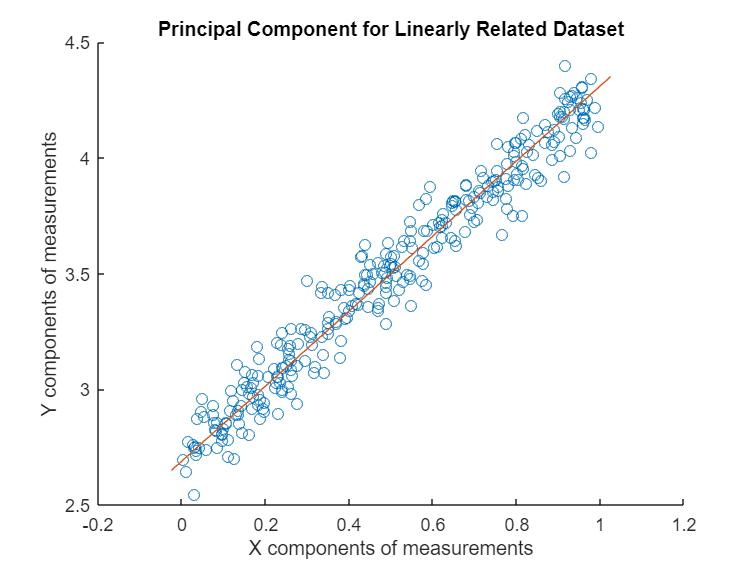

xm = sum(x)/length(x); %empirical mean
ym = sum(y)/length(y); %empirical mean
p = [x';y'];   %dataset
cov = p*p'/(length(x)-1) - (length(x))*[xm;ym]*[xm,ym]/(length(x)-1); %empirical covariance

[v, ~] = eigs(cov, 1);  %principal eigenvector
scatter(x,y); hold on;
plot(linspace(-1,1,10)*(v(1))+xm,linspace(-1,1,10)*(v(2))+ym);  %line passing through empirical mean along principal eigenvector
title("Principal Component for Linearly Related Dataset");
xlabel('X components of measurements')
ylabel('Y components of measurements')
hold off;

• (5 points) Repeat the same analysis for the set of points in "points2D_Set2.mat". Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X. Compared to the result on the other set of points, justify the quality of the approximation resulting in this question using logical arguments. 

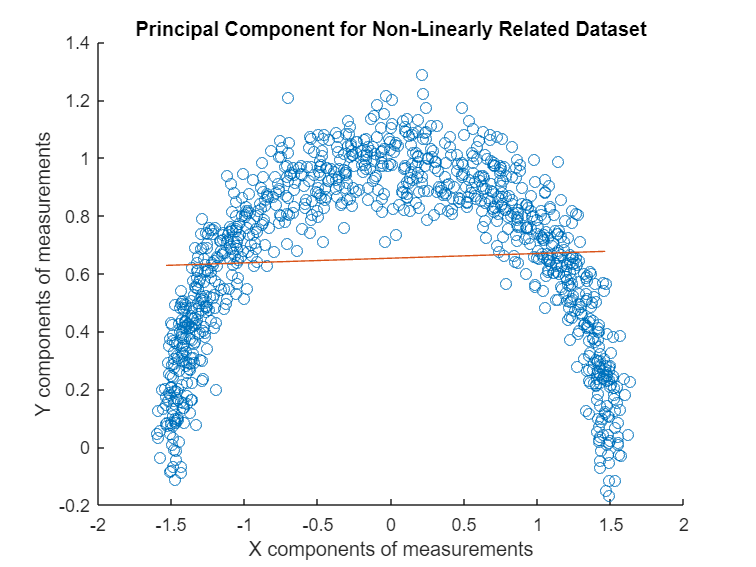

load("../data/points2D_Set2.mat"); % if current path is inside code directory

xm = sum(x)/length(x);  %empirical mean
ym = sum(y)/length(y);   %empirical mean
p = [x';y'];   %dataset
%sample cov   
cov = p*p'/(length(x)-1) - (length(x))*[xm;ym]*[xm,ym]/(length(x)-1);

%same as above
[v, ~] = eigs(cov, 1); 
scatter(x,y); hold on;
plot(linspace(-1.5,1.5,10)*(v(1))+xm,linspace(-1.5,1.5,10)*(v(2))+ym);
title("Principal Component for Non-Linearly Related Dataset");
xlabel('X components of measurements')
ylabel('Y components of measurements')
hold off;

PCA gives the the **direction** of maximum variance(a direction in the cartesian system can be viewed as a line in that direction). 

The previous set of points had a fairly linear relationship between Y and X(as is evident from the scatter plot) and hence, the direction of variance of the data was along that line, which is incidentally the same "direction" that PCA tells us. Hence, the approximation using PCA on the first set of data points almost exactly fits the data because the relationship between the variables was close to linear.

Coming to the second set of points, these points have not even something close to a linear relationship. So, in this case, PCA just gives us the direction of maximum variation but this is not so related to the data(opposite to the case for the first dataset), because there is no single direction in which "most" of the data lies. Hence, the approximation by PCA in this case would seem nothing more than just a mathematical quantity because of the non linear nature of the relationship, but it was far more intuitive in the first dataset.

But on observing the data of the second data set, we observe that the relationship is not linear but it still has only one degree of freedom(along the **arc**). So a possible transformation of the data set to make it linear would help in applying a PCA-like analysis.